%This code reproduces Extended Fig3 from the second rebuttal submitted to Nature2020
%paper (Nienhuis et al., 2020). It needs v1 dataset provided by Jaap Nienhuis

v1 = load ('V1\GlobalDeltaData_v1.mat');%provided by Jaap Nienhuis
v11 = load ('V1.1\GlobalDeltaData.mat');
v2 = load ('V2\GlobalDeltaData.mat') %from https://github.com/jhnienhuis/GlobalDeltaChange
v2.ee = load('V2\land_area_change\GlobalDeltaData_AreaChange.mat');
load 'V1/BasinID2';
BasinID2 = double(BasinID2);

v2 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
           BasinID2: [10848×1 int64]
      BasinID_ATLAS: [10848×1 int64]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
                 Hs: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
              QWave: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
      RiverID_ATLAS: [1×10848 int64]
           TidalAmp: [10848×1 double]
                 Tp: [10848×1 double]
        channel_len: [10848×30 double]
    channel_len_lat: [10848×30 double]
    channel_len_lon: [10848×30 double]
      channel_slope: [10848×1 double]
         delta_name: [10848×1 s

%Max 100
Max_deltas100 = readtable('EE_Max100Big_polys_change.csv');

Max_deltas100_orig = readtable('GlobalDeltaMax100ID.csv'); %From https://github.com/jhnienhuis/GlobalDeltaChange/tree/master/land_area_change
[~,DeltaID_Max100] = ismember(Max_deltas100.ID, BasinID2);
[~,DeltaID_Max100_orig] = ismember(Max_deltas100_orig.BasinID2, BasinID2);
Max_deltas100_change = Max_deltas100.change2/28;


%Outlier delta
find(v2.ee.net_aqua == max(v2.ee.net_aqua)) % Find the outlier mouth

ans = 4717

GangesQdist = v2.QRiver_dist(4717)

GangesQdist = 72644

GangesQprist = v2.QRiver_prist(4717)

GangesQprist = 53453

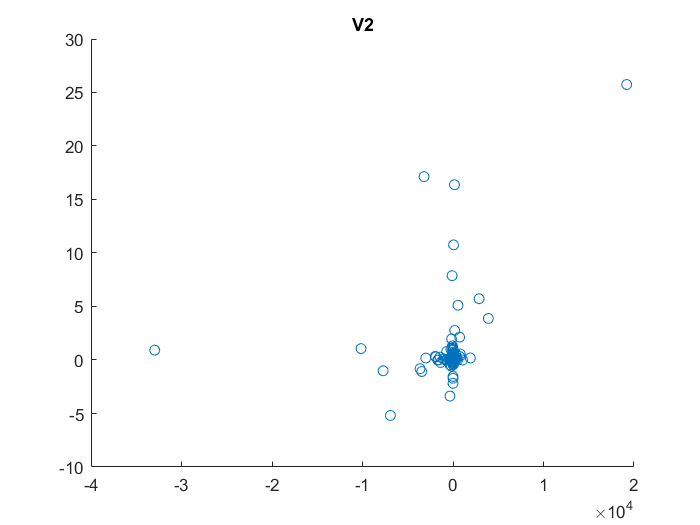

%V2 data check
clf
scatter(v2.QRiver_dist-v2.QRiver_prist, v2.ee.net_aqua)
title 'V2'

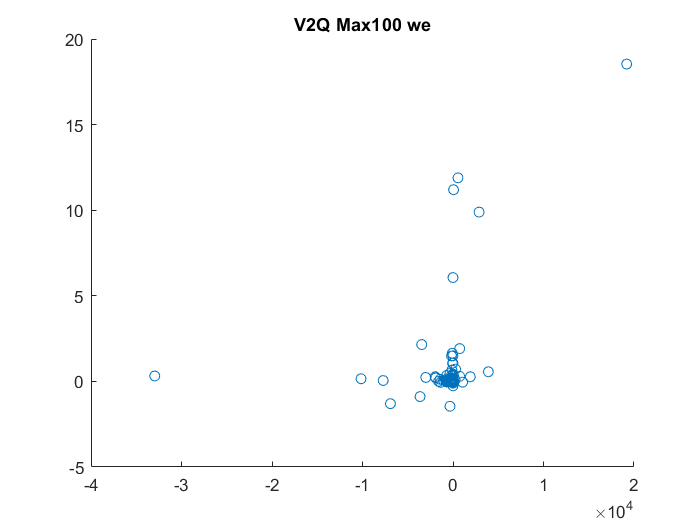


% Qdist-Qpristv2 cu Max100(we)
scatter(v2.QRiver_dist(DeltaID_Max100)-v2.QRiver_prist(DeltaID_Max100), Max_deltas100_change)
title 'V2Q Max100 we'

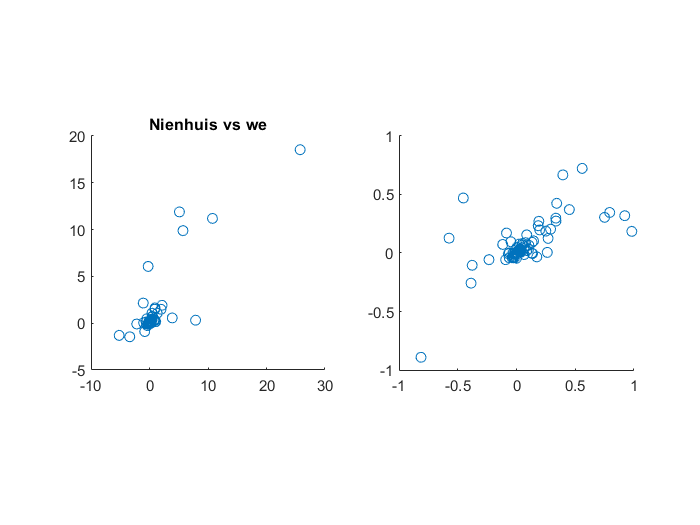


% Japp vs we max 100
subplot(1,2,1)
scatter(v2.ee.net_aqua(DeltaID_Max100), Max_deltas100_change)
title 'Nienhuis vs we'
axis square
subplot(1,2,2)
scatter(v2.ee.net_aqua(DeltaID_Max100), Max_deltas100_change)
xlim([-1 1])
ylim([-1 1])
axis square

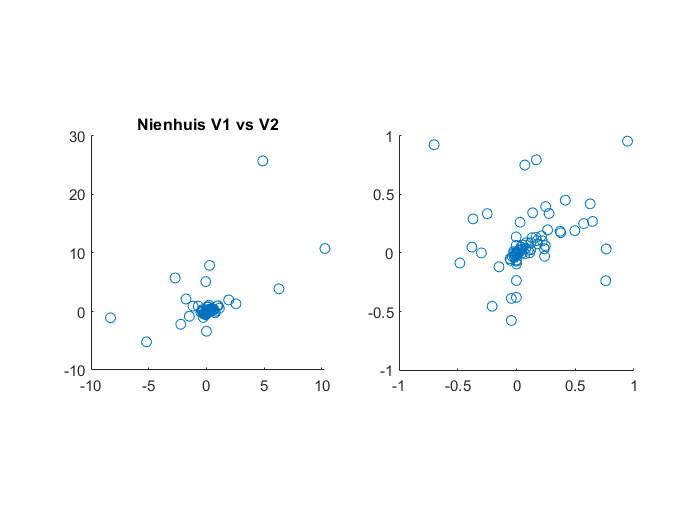


% Jappv1 vs Jaapv2
clf
subplot(1,2,1)
scatter(v1.ee.net_aqua(DeltaID_Max100), v2.ee.net_aqua(DeltaID_Max100))
title 'Nienhuis V1 vs V2'
axis square

subplot(1,2,2)
scatter(v1.ee.net_aqua(DeltaID_Max100), v2.ee.net_aqua(DeltaID_Max100))
xlim([-1 1])
ylim([-1 1])
axis square


%find outlier mouth in v2 - maximum
find(v2.ee.net_aqua == max(v2.ee.net_aqua))

ans = 4717

regression_QdistQprist_V2 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE        tStat       pValue  
                   __________    __________    ______    __________

    (Intercept)      0.013965     0.0034858    4.0063    6.2082e-05
    x1             0.00027637    8.6377e-06    31.995    9.918e-215


Number of observations: 10848, Error degrees of freedom: 10846
Root Mean Squared Error: 0.363
R-squared: 0.0862,  Adjusted R-Squared: 0.0862
F-statistic vs. constant model: 1.02e+03, p-value = 9.92e-215

regression_QdistQprist_V2Max100 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE          tStat       pValue 
                   __________    __________    _________    ________

    (Intercept)       0.64485       0.33295       1.9368    0.055842
    x1             3.9173e-07    8.5716e-05    0.0045701     0.99636


Number of observations: 94, Error degrees of freedom: 92
Root Mean Squared Error: 3.2
R-squared: 2.27e-07,  Adjusted R-Squared: -0.0109
F-statistic vs. constant model: 2.09e-05, p-value = 0.996

regression_QdistQprist_Max100 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE        tStat       pValue  
                   __________    __________    ______    __________

    (Intercept)       0.91679       0.26762    3.4257    0.00091816
    x1             0.00024983    6.2035e-05    4.0272    0.00011597


Number of observations: 94, Error degrees of freedom: 92
Root Mean Squared Error: 2.57
R-squared: 0.15,  Adjusted R-Squared: 0.141
F-statistic vs. constant model: 16.2, p-value = 0.000116

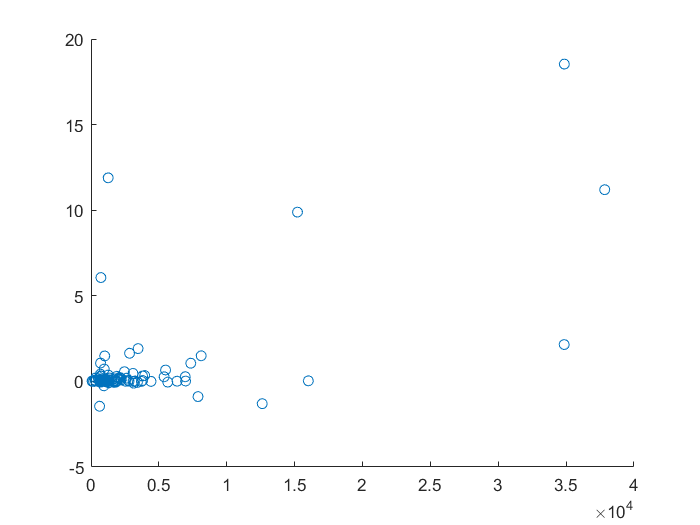

clf
scatter(v1.QRiver_prist(DeltaID_Max100), Max_deltas100_change)

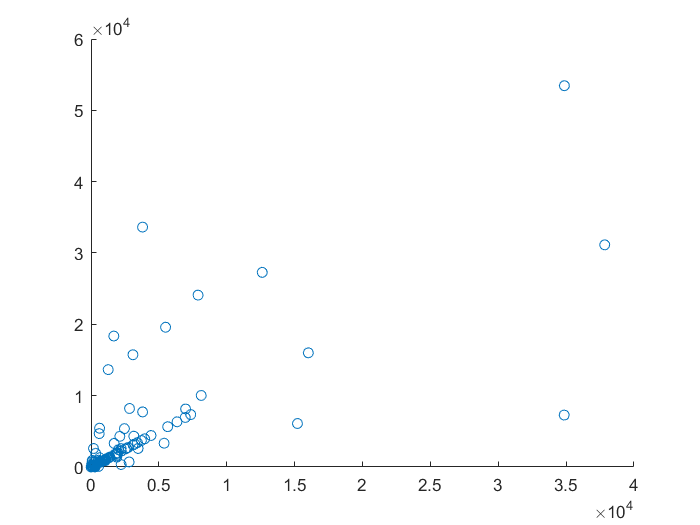

clf
scatter(v1.QRiver_prist, v2.QRiver_prist)

%Partially based on code provided by Jaap Nienhuis
%morphologic dominance for each delta
%[~,mor] = max([v1.QWave,v1.QRiver_prist,v1.QTide],[],2);

%relative increase/decrease
flux_ratio1 = v1.QRiver_dist./v1.QRiver_prist;
flux_ratio2 = v2.QRiver_dist./v2.QRiver_prist;

%wave or tide reworking?
wave_rework1 = v1.QWave>v1.QTide;
wave_rework2 = v2.QWave>v2.QTide;

%get 
v1Max100_our = v2.ee.net_aqua;
v1Max100_our(DeltaID_Max100) =  Max_deltas100_change;

%land loss of deltas
sum(v1.ee.net_aqua(flux_ratio1<0.5))

ans = -11.6552

sum(v2.ee.net_aqua(flux_ratio2<0.5))

ans = 22.3341

sum(v1Max100_our(flux_ratio2<0.5))

ans = 21.7575


%land gain
sum(v1.ee.net_aqua(flux_ratio1>1.5))

ans = 25.0652

sum(v2.ee.net_aqua(flux_ratio2>1.5))

ans = 20.8611

sum(v1Max100_our(flux_ratio2>1.5))

ans = 17.5363


%difference between wave and tidal reworking
sum(v1.ee.net_aqua(flux_ratio1<0.5 & wave_rework1==1))

ans = -12.4399

sum(v1.ee.net_aqua(flux_ratio1<0.5 & wave_rework1==0))

ans = 0.7847


sum(v2.ee.net_aqua(flux_ratio2<0.5 & wave_rework2==1))

ans = 3.9422

sum(v2.ee.net_aqua(flux_ratio2<0.5 & wave_rework2==0))

ans = 18.3919

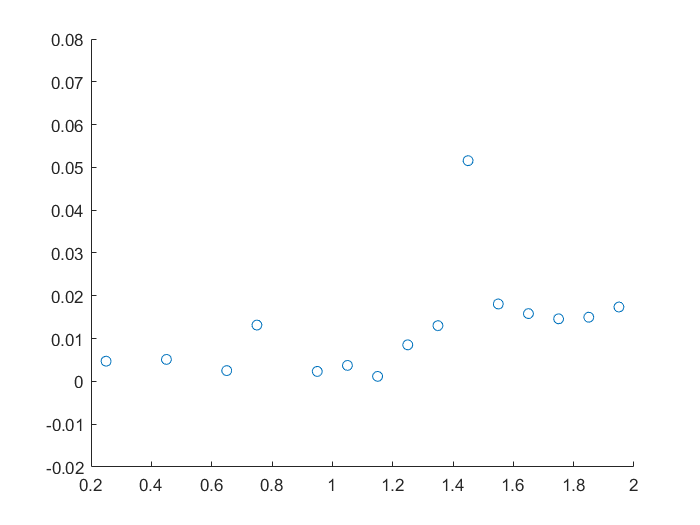


%Code partially provided by Jaap Nienhuis
%scatter plot V1
flux_ratio1(flux_ratio1<0) = 0; flux_ratio1(flux_ratio1>2) = 2; 
bin_edg = [0:0.1:2];
[y1] = discretize(flux_ratio1,bin_edg);
f_y1 = accumarray(y1,v1.ee.net_aqua,[],@mean);
scatter(bin_edg(1:end-1)+0.05,f_y1)
ylim ([-0.02 0.08])

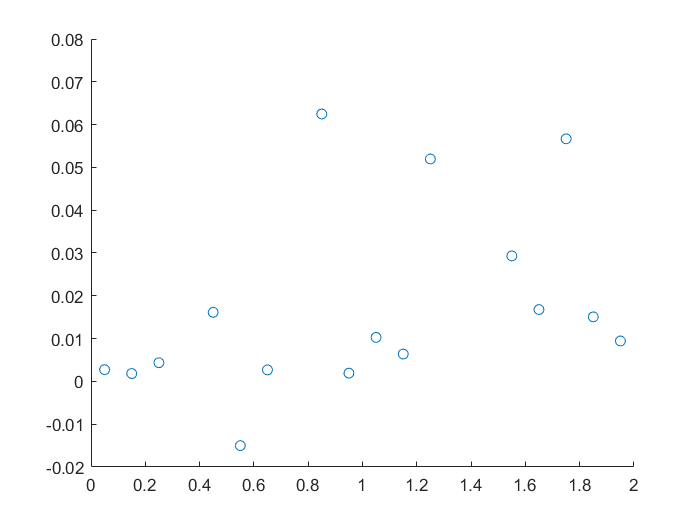


%scatter plot V2
flux_ratio2(flux_ratio2<0) = 0; flux_ratio2(flux_ratio2>2) = 2; 
bin_edg = [0:0.1:2];
[y2] = discretize(flux_ratio2,bin_edg);
f_y2 = accumarray(y2,v2.ee.net_aqua,[],@mean);
scatter(bin_edg(1:end-1)+0.05,f_y2)
ylim ([-0.02 0.08])

% regressions
reg_v1 = fitlm(1:20,f_y1)

reg_v1 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE         tStat      pValue 
                   _________    _________    _______    ________

    (Intercept)     -0.04155     0.018833    -2.2063    0.040599
    x1             0.0040225    0.0015721     2.5586     0.01974


Number of observations: 20, Error degrees of freedom: 18
Root Mean Squared Error: 0.0405
R-squared: 0.267,  Adjusted R-Squared: 0.226
F-statistic vs. constant model: 6.55, p-value = 0.0197

reg_v2 = fitlm(1:20,f_y2)

reg_v2 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE         tStat     pValue 
                   _________    _________    _______    _______

    (Intercept)     0.010612     0.049053    0.21634    0.83116
    x1             0.0037607    0.0040949    0.91839    0.37056


Number of observations: 20, Error degrees of freedom: 18
Root Mean Squared Error: 0.106
R-squared: 0.0448,  Adjusted R-Squared: -0.00831
F-statistic vs. constant model: 0.843, p-value = 0.371

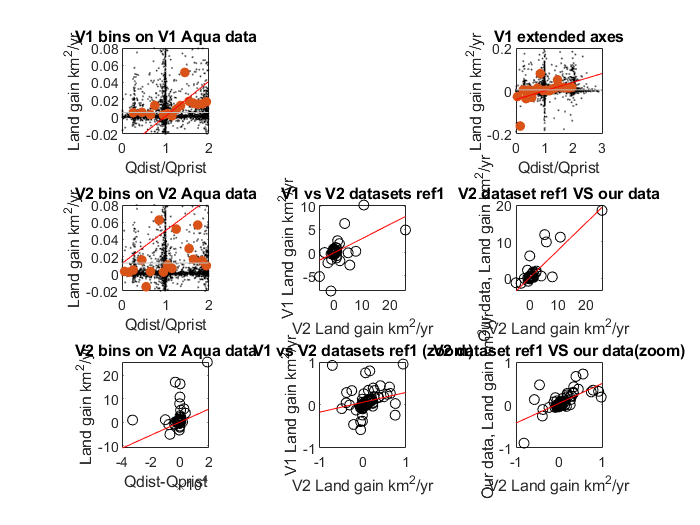

%All data (y scale) bin means
clf

ax1 = subplot(3,3,1);

scatter(v1.QRiver_dist./v1.QRiver_prist, v1.ee.net_aqua, 0.05,'.','k')
hold on
plot(bin_edg(1:end-1)+0.05,f_y1,'.', 'MarkerSize',20)
%plot(edges+0.05, ee_bin_means_aqua,'.', 'MarkerSize',20)
h1 = lsline(ax1);
h1(1).Color = 'r'; % regression only cut data bins
%h1(2).Color = 'b'; % regression all data
%h1(2).LineWidth = 1.5;
xlim([0 2])
ylim([-0.02 0.08])
xlabel 'Qdist/Qprist'
ylabel 'Land gain km^2/yr'
title 'V1 bins on V1 Aqua data'
axis square
box on

ax2 = subplot(3,3,3);

scatter(v1.QRiver_dist./v1.QRiver_prist, v1.ee.net_aqua, 0.05,'.','k')
hold on
plot(bin_edg(1:end-1)+0.05,f_y1,'.', 'MarkerSize',20)
%plot(edges+0.05, ee_bin_means_aqua,'.', 'MarkerSize',20)
h1 = lsline(ax2);
h1(1).Color = 'r'; % regression only cut data bins
%h1(2).Color = 'b'; % regression all data
%h1(2).LineWidth = 1.5;
xlim([0 3])
ylim([-0.2 0.2])
xlabel 'Qdist/Qprist'
ylabel 'Land gain km^2/yr'
title 'V1 extended axes'
axis square
box on

ax3 = subplot(3,3,4);
scatter(v2.QRiver_dist./v2.QRiver_prist, v2.ee.net_aqua, 0.05,'.','k')
hold on
plot(bin_edg(1:end-1)+0.05,f_y2,'.', 'MarkerSize',20)
%plot(edges+0.05, ee_bin_means_aqua,'.', 'MarkerSize',20)
h1 = lsline(ax3);
h1(1).Color = 'r'; % regression only cut data bins
%h1(2).Color = 'b'; % regression all data
%h1(2).LineWidth = 1.5;
xlim([0 2])
ylim([-0.02 0.08])
xlabel 'Qdist/Qprist'
ylabel 'Land gain km^2/yr'
title 'V2 bins on V2 Aqua data'
axis square
box on

ax4 = subplot(3,3,7);
scatter(v2.QRiver_dist-v2.QRiver_prist, v2.ee.net_aqua, 'k')
%hold on
%plot(bin_edg(1:end-1)+0.05,f_y2,'.', 'MarkerSize',20)
%plot(edges+0.05, ee_bin_means_aqua,'.', 'MarkerSize',20)
h1 = lsline(ax4);
h1(1).Color = 'r'; % regression only cut data bins
%h1(2).Color = 'b'; % regression all data
%h1(2).LineWidth = 1.5;
xlabel 'Qdist-Qprist'
ylabel 'Land gain km^2/yr'
title 'V2 bins on V2 Aqua data'
axis square
box on


ax5 = subplot(3,3,5);
scatter(v2.ee.net_aqua(DeltaID_Max100), v1.ee.net_aqua(DeltaID_Max100), 'k')
%hold on
%plot(bin_edg(1:end-1)+0.05,f_y2,'.', 'MarkerSize',20)
%plot(edges+0.05, ee_bin_means_aqua,'.', 'MarkerSize',20)
h1 = lsline(ax5);
h1(1).Color = 'r'; % regression only cut data bins
%h1(2).Color = 'b'; % regression all data
%h1(2).LineWidth = 1.5;
xlabel 'V2 Land gain km^2/yr'
ylabel 'V1 Land gain km^2/yr'
title 'V1 vs V2 datasets ref1'
axis square
box on

ax6 = subplot(3,3,8);%zoom plot

V1Max100 = v1.ee.net_aqua(DeltaID_Max100);
V2Max100 = v2.ee.net_aqua(DeltaID_Max100);
V1V2_zoom_log = V1Max100 > -1 & V1Max100 < 1 & V2Max100 > -1 & V2Max100 < 1;
sum(V1V2_zoom_log); %73
scatter(V1Max100(V1V2_zoom_log), V2Max100(V1V2_zoom_log), 'k')
%hold on
%plot(bin_edg(1:end-1)+0.05,f_y2,'.', 'MarkerSize',20)
%plot(edges+0.05, ee_bin_means_aqua,'.', 'MarkerSize',20)

h1 = lsline(ax6);
h1(1).Color = 'r'; % regression only cut data bins
%h1(2).Color = 'b'; % regression all data
%h1(2).LineWidth = 1.5;
xlabel 'V2 Land gain km^2/yr'
ylabel 'V1 Land gain km^2/yr'
title 'V1 vs V2 datasets ref1 (zoom)'
xlim([-1 1])
ylim([-1 1])
axis square
box on


ax7 = subplot(3,3,6);
scatter(v2.ee.net_aqua(DeltaID_Max100), Max_deltas100_change, 'k')
%hold on
%plot(bin_edg(1:end-1)+0.05,f_y2,'.', 'MarkerSize',20)
%plot(edges+0.05, ee_bin_means_aqua,'.', 'MarkerSize',20)
h1 = lsline(ax7);
h1(1).Color = 'r'; % regression only cut data bins
%h1(2).Color = 'b'; % regression all data
%h1(2).LineWidth = 1.5;
xlabel 'V2 Land gain km^2/yr'
ylabel 'Our data, Land gain km^2/yr'
title 'V2 dataset ref1 VS our data'
axis square
box on

ax8 = subplot(3,3,9);

V1V2We_zoom_log = Max_deltas100_change > -1 & Max_deltas100_change < 1 & V2Max100 > -1 & V2Max100 < 1;
sum(V1V2We_zoom_log); %73

scatter(V2Max100(V1V2We_zoom_log), Max_deltas100_change(V1V2We_zoom_log), 'k')
%hold on
%plot(bin_edg(1:end-1)+0.05,f_y2,'.', 'MarkerSize',20)
%plot(edges+0.05, ee_bin_means_aqua,'.', 'MarkerSize',20)
h1 = lsline(ax8);
h1(1).Color = 'r'; % regression only cut data bins
%h1(2).Color = 'b'; % regression all data
%h1(2).LineWidth = 1.5;
xlabel 'V2 Land gain km^2/yr'
ylabel 'Our data, Land gain km^2/yr'
title 'V2 dataset ref1 VS our data(zoom)'
xlim([-1 1])
ylim([-1 1])
axis square
box on

reg_v2_ratio_on_v2aqua = fitlm(v2.QRiver_dist./v2.QRiver_prist, v2.ee.net_aqua)

reg_v2bins_on_v2aqua = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate          SE          tStat        pValue  
                   ___________    __________    _________    __________

    (Intercept)       0.012505     0.0036467       3.4292    0.00060758
    x1             -1.3949e-12    3.2895e-11    -0.042403       0.96618


Number of observations: 10848, Error degrees of freedom: 10846
Root Mean Squared Error: 0.38
R-squared: 1.66e-07,  Adjusted R-Squared: -9.2e-05
F-statistic vs. constant model: 0.0018, p-value = 0.966

reg_v2_dif_v2aqua = fitlm(v2.QRiver_dist-v2.QRiver_prist, v2.ee.net_aqua)

reg_v2bins_dif_v2aqua = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE        tStat       pValue  
                   __________    __________    ______    __________

    (Intercept)      0.013965     0.0034858    4.0063    6.2082e-05
    x1             0.00027637    8.6377e-06    31.995    9.918e-215


Number of observations: 10848, Error degrees of freedom: 10846
Root Mean Squared Error: 0.363
R-squared: 0.0862,  Adjusted R-Squared: 0.0862
F-statistic vs. constant model: 1.02e+03, p-value = 9.92e-215


reg_v2VSv1 = fitlm(v2.ee.net_aqua(DeltaID_Max100), v1.ee.net_aqua(DeltaID_Max100))

reg_v2VSv1 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue 
                   _________    _______    ________    ________

    (Intercept)    -0.066343    0.16022    -0.41407     0.67979
    x1               0.30573    0.04963      6.1602    1.89e-08


Number of observations: 94, Error degrees of freedom: 92
Root Mean Squared Error: 1.52
R-squared: 0.292,  Adjusted R-Squared: 0.284
F-statistic vs. constant model: 37.9, p-value = 1.89e-08

reg_v2VSv1_zoom = fitlm(V1Max100(V1V2_zoom_log), V2Max100(V1V2_zoom_log))

reg_v2VSv1_zoom = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat      pValue 
                   ________    ________    ______    ________

    (Intercept)    0.061228    0.030657    1.9972    0.049534
    x1              0.22834     0.10982    2.0792    0.041111


Number of observations: 75, Error degrees of freedom: 73
Root Mean Squared Error: 0.251
R-squared: 0.0559,  Adjusted R-Squared: 0.043
F-statistic vs. constant model: 4.32, p-value = 0.0411


reg_v2VSwe = fitlm(v2.ee.net_aqua(DeltaID_Max100), Max_deltas100_change)

reg_v2VSwe = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)    0.29085      0.15482    1.8787      0.063454
    x1             0.74045     0.047955     15.44    2.7926e-27


Number of observations: 94, Error degrees of freedom: 92
Root Mean Squared Error: 1.47
R-squared: 0.722,  Adjusted R-Squared: 0.719
F-statistic vs. constant model: 238, p-value = 2.79e-27

reg_v2VSwe_zoom = fitlm(V2Max100(V1V2We_zoom_log), Max_deltas100_change(V1V2We_zoom_log))

reg_v2VSwe_zoom = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)    0.03874     0.018097    2.1407       0.03564
    x1             0.45953     0.063067    7.2865    3.0557e-10


Number of observations: 75, Error degrees of freedom: 73
Root Mean Squared Error: 0.151
R-squared: 0.421,  Adjusted R-Squared: 0.413
F-statistic vs. constant model: 53.1, p-value = 3.06e-10


%(v1.ee.net_aqua(DeltaID_Max100), v2.ee.net_aqua(DeltaID_Max100)

sum(v2.ee.net_aqua)
sum(v1.ee.net_aqua)
sum(v2.ee.net_aqua(DeltaID_Max100))
sum(v1.ee.net_aqua(DeltaID_Max100))
sum(Max_deltas100_change)